### Openning WVM output

ncfile = NetCDFFile('run18_icR_iner07_tide014_lat32_geo0065_N0052_boussinesq_res512.nc');

wvt = WVTransform.waveVortexTransformFromFile(ncfile.path, iTime=Inf);

WVTransformBoussinesq initialized from Ap, Am, A0.
NetCDFFile closed.
NetCDFFile closed.


%seconds since 1970-01-01 00:00:00
t = ncfile.readVariables('mooring/t');
num = t / 86400 + datenum(1970,1,1);

id = ncfile.readVariables('mooring/mooring_id');
x = ncfile.readVariables('mooring/mooring_x');
y = ncfile.readVariables('mooring/mooring_y');
z = ncfile.readVariables('mooring/mooring_z');

day50=round(28801*0.2)+1;

t = ncfile.readVariables('mooring/t');
mooring1_t=t(day50:end);

u = ncfile.readVariables('mooring/mooring_u_w');
mooring1_u=squeeze(u(57,1,day50:end));

v = ncfile.readVariables('mooring/mooring_v_w');
mooring1_v=squeeze(v(57,1,day50:end));

w = ncfile.readVariables('mooring/mooring_w_w');
mooring1_w=squeeze(w(57,1,day50:end));

eta = ncfile.readVariables('mooring/mooring_eta_w');
mooring1_eta=squeeze(eta(57,1,day50:end));

%N2=ncfile.readVariables('mooring/N2');
%mooring1_N2=squeeze(N2(57,1,day50:end));

### Initialize the toolbox

%Stratification 1 - Exponential
% f0=2*7.2921e-5*sind(latitude);
latExp=33;
L_gm = 1300;
N0 = 3*2*pi/3600;
N2funcExp = @(z) N0*N0*exp(2*z/L_gm);
LzExp=4000;
tic
igw = InternalGravityWaveSpectrum(N2funcExp,LzExp,nModes=56,nK=200,latitude=latExp);
toc

### Distributing energy

igw= igw.assignEnergySpectrum("gm");

 
cv_mooring = shiftdim( mooring1_u + sqrt(-1)*mooring1_v, 2);
[PSI,LAMBDA] = sleptap(length(mooring1_t),5);
[omega_p, Spp, Snn, Spn] = mspec(mooring1_t(2)-mooring1_t(1),cv_mooring,PSI);


plot(omega_p*(24*3600)/(2*pi),(Spp+Snn)/wvt.rho0,'LineWidth',2,"Color",'k','DisplayName', 'S_{wvt}');

xlim([omega_p(2)*(24*3600)/(2*pi) omega_p(end)*(24*3600)/(2*pi)]),xlog,ylog%,ylim(10.^[-1 3])

lat=32;
hold on

hold on
z1=-511.8385;
Nmax=sqrt(N2funcExp(-z1))
omegaVector=10.^linspace(log10(igw.f0),log10(Nmax),100);

%figure(2)
energyAtFreq = igw.energyAtFrequencies(z1, "HKE", omegaVector=omegaVector, plot=0);
freqCPD = (omegaVector)*(24*3600)/(2*pi);
loglog(freqCPD, energyAtFreq * 1000, 'LineWidth', 2,'DisplayName','S_{GM+}',Color=[0, 0.5, 0.45]);
xlog,ylog

igw= igw.removeAllEnergy;
igw= igw.assignEnergySpectrum("general");

hold on
z1=-511.8385;
Nmax=sqrt(N2funcExp(-z1))
omegaVector=10.^linspace(log10(igw.f0),log10(Nmax),100);

%figure(2)

energyAtFreq = igw.energyAtFrequencies(z1, "HKE", omegaVector=omegaVector, plot=0);
freqCPD = (omegaVector)*(24*3600)/(2*pi);
loglog(freqCPD, energyAtFreq * 1000, 'LineWidth', 2, 'DisplayName', 'S_{gen+}',Color=[0.5, 0.8, 0.75]);
xlog,ylog

vlines(corfreq(lat)/2/pi*24,'2G--')
vlines(0.5175/2/pi*24,':')
xline(2.1996e-4*(24*3600)/(2*pi),'.-')

legend('S_{wvt}','S_{gm}','S_{gen+}','Location', 'southwest')

xlabel('Frequency [cycles/day]')
ylabel('E [m^2s^{-2}]')

annotation('textbox', [0.70 0.80 0.1 0.1], 'String', 'z=512m', ...
    'FontSize', 14, 'BackgroundColor', 'white', 'EdgeColor', 'k','FontSize',10)

ax = gca;
ax.FontSize = 12;               
ax.Title.FontSize = 14;        
ax.XLabel.FontSize = 12;        
ax.YLabel.FontSize = 12; 

set(gcf, 'Units', 'centimeters', 'Position', [5,5, 15, 13]);

% Salvar com tamanho e qualidade especificados
%exportgraphics(gcf, ['SGen_LF_freq', '.png'], 'Resolution', 300);

#### Rotary spectrum

Srp=(5*10^-3)*(wvt.f./omegaVector).*(1./(omegaVector.^2 - wvt.f^2).^(0.5)).*((1-(wvt.f./omegaVector)).^2);
Srn=10^-3*(wvt.f./omegaVector).*(1./sqrt(omegaVector.^2 - wvt.f^2)).*((1+(wvt.f./omegaVector)).^2);

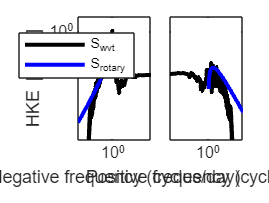

tiledlayout(1,2, 'TileSpacing', 'compact')
ax1 = nexttile(1);
set(ax1,'xdir','reverse')
set(ax1,'XScale','log')
set(ax1,'YScale','log')
set(ax1,"YLim",[10^-7, 10])
ylabel(ax1,"HKE [m^2s^{-2}]")
xlabel(ax1,"Negative frequency (cycles/day)")

%axis tight
box on
hold on

ax2 = nexttile(2);
set(ax2,'XScale','log')
set(ax2,'YScale','log')
set(ax2,"YLim",[10^-7, 10])
set(ax2, 'YTicklabel', [])
xlabel(ax2,"Positive frequency (cycles/day)")
%axis tight
box on
hold on


% negative
loglog(ax1,omega_p*86400/2/pi,fliplr(Snn/wvt.rho0),Color="k",LineWidth=2);
loglog(ax1,omegaVector'*86400/2/pi,fliplr(Srn'/wvt.rho0),Color="b",LineWidth=2);

% positive
loglog(ax2,omega_p*86400/2/pi,fliplr(Spp/wvt.rho0),Color="k",LineWidth=2);
loglog(ax2,omegaVector*86400/2/pi,fliplr(Srp'/wvt.rho0),Color="b",LineWidth=2);

legend(ax1,"S_{wvt}","S_{rotary}")

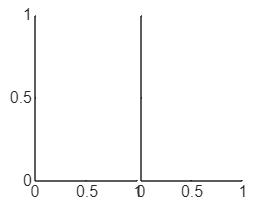


packfig(1,2)